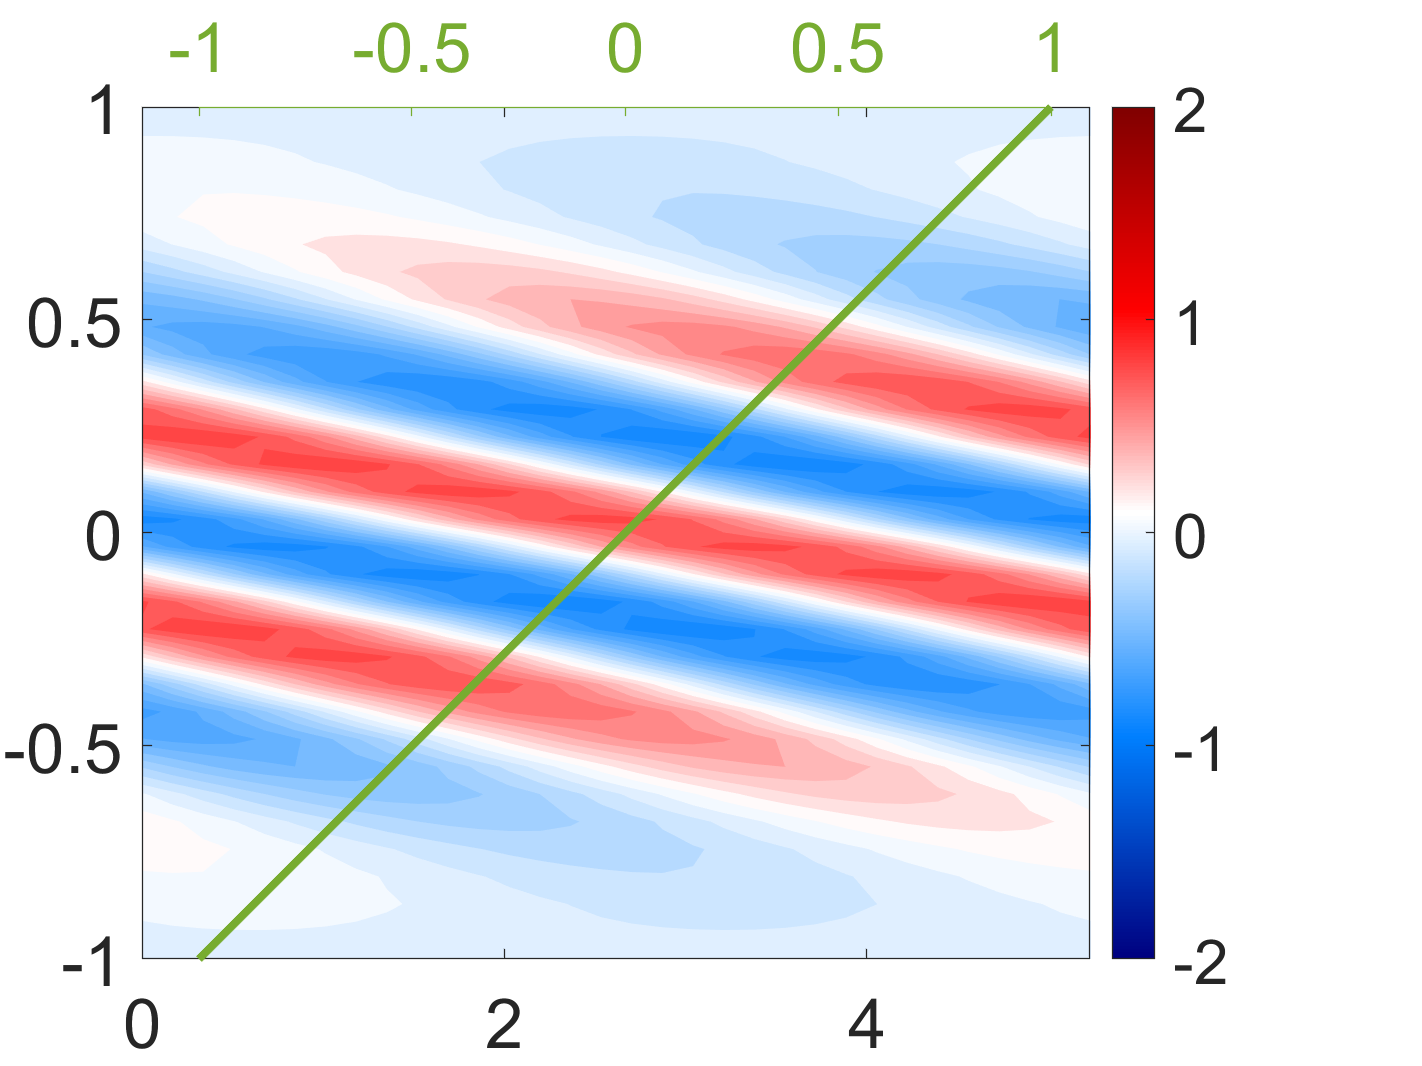

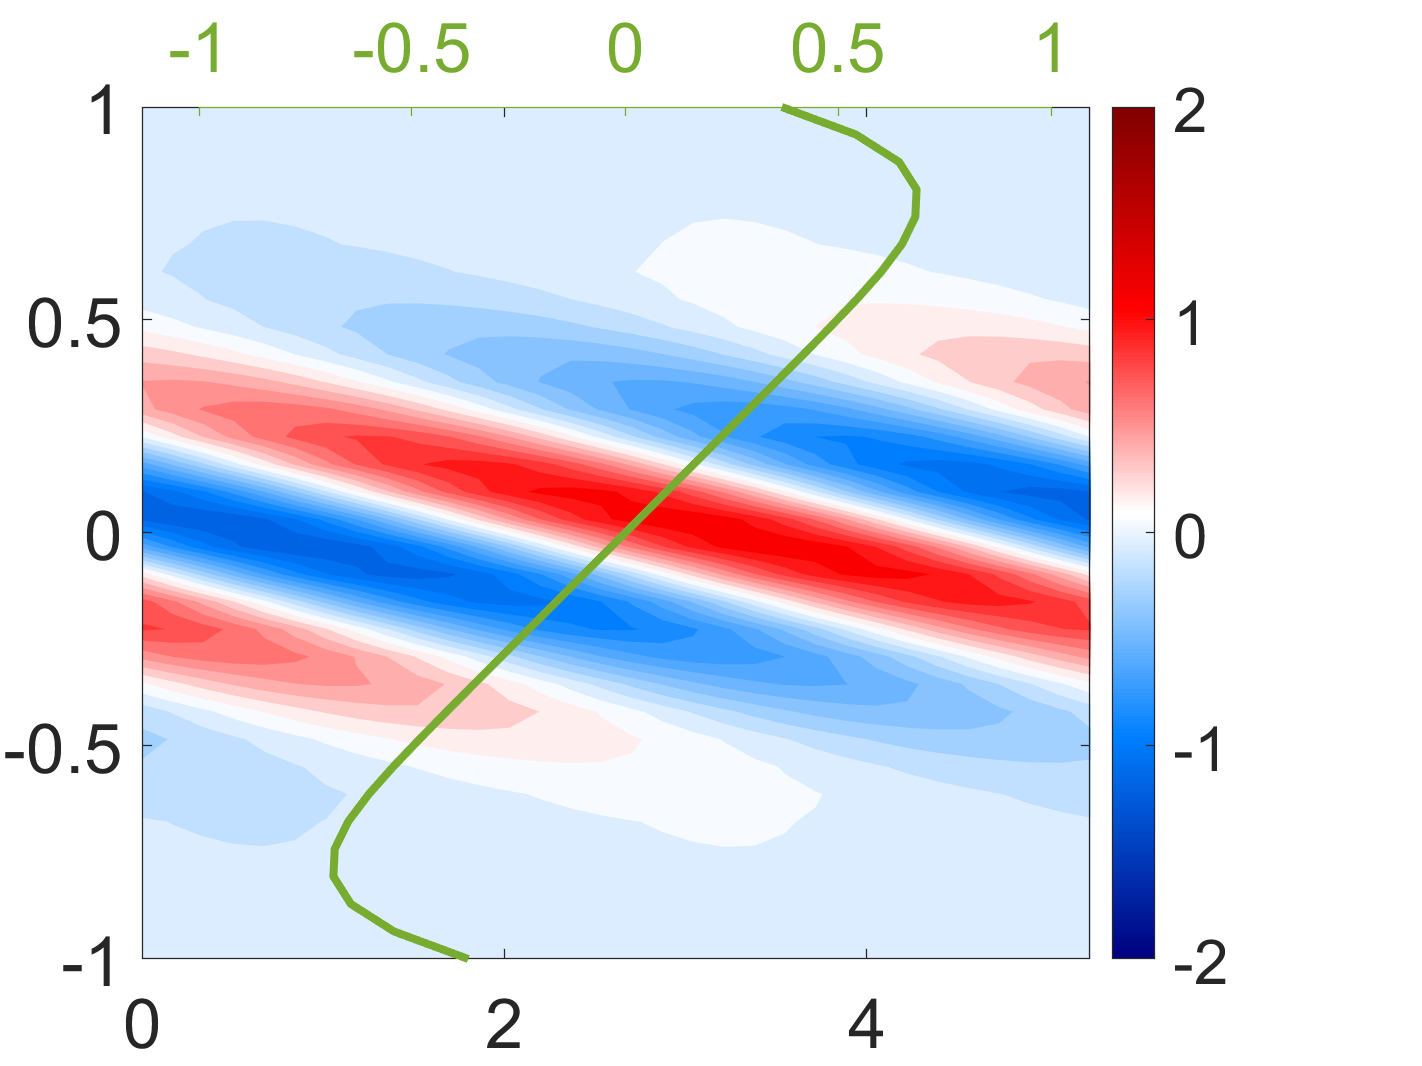

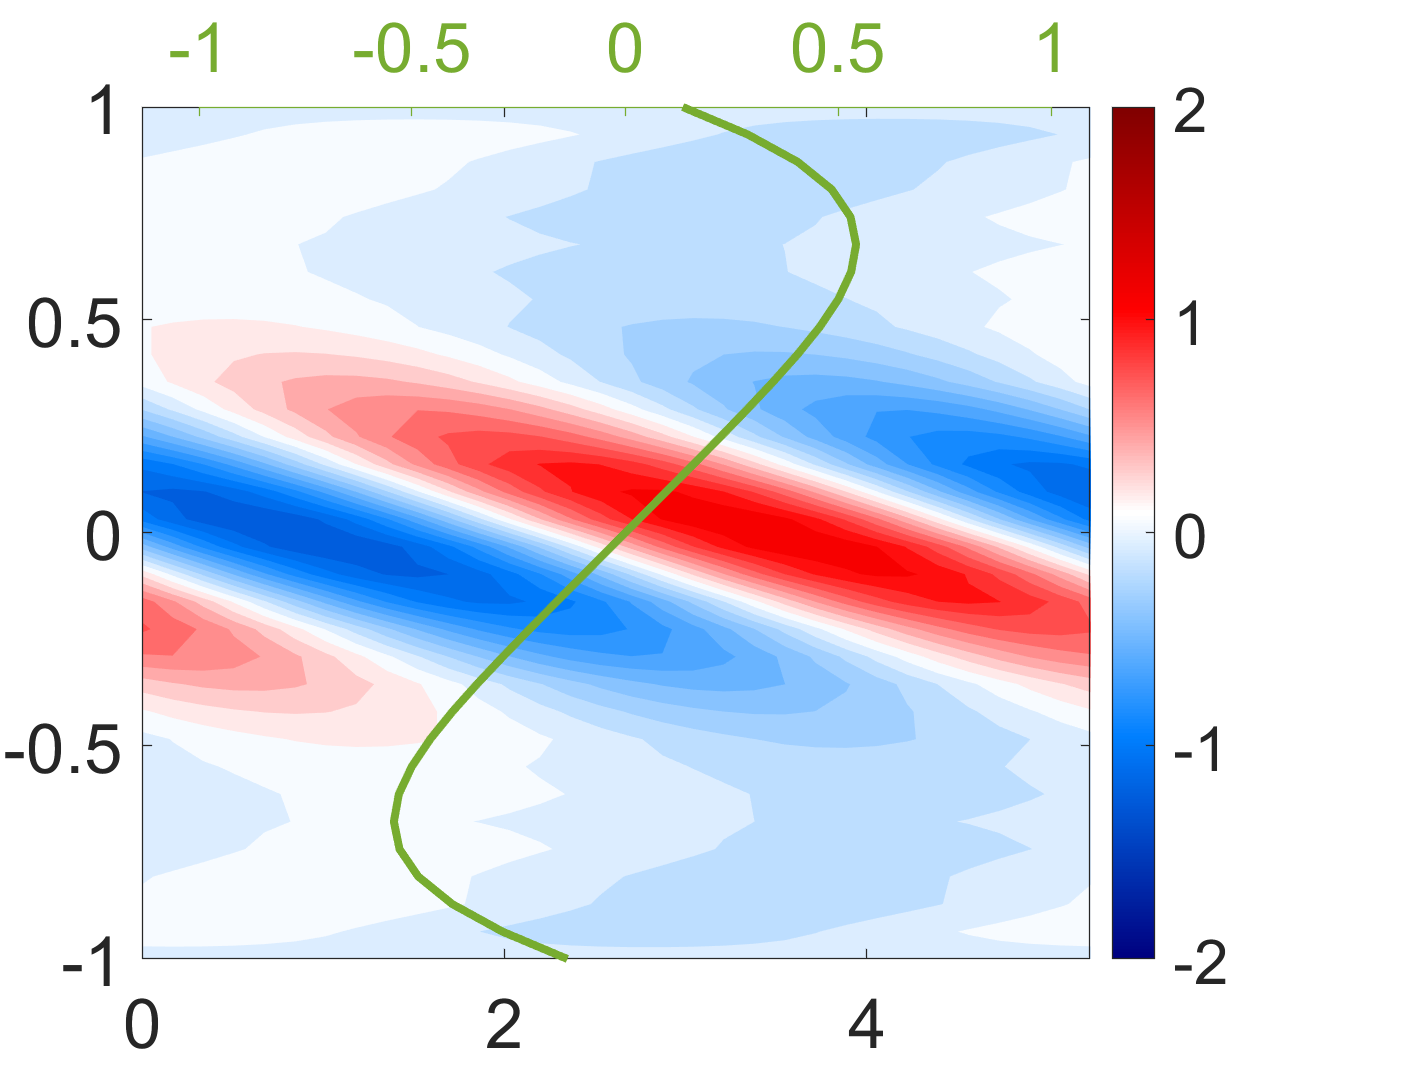

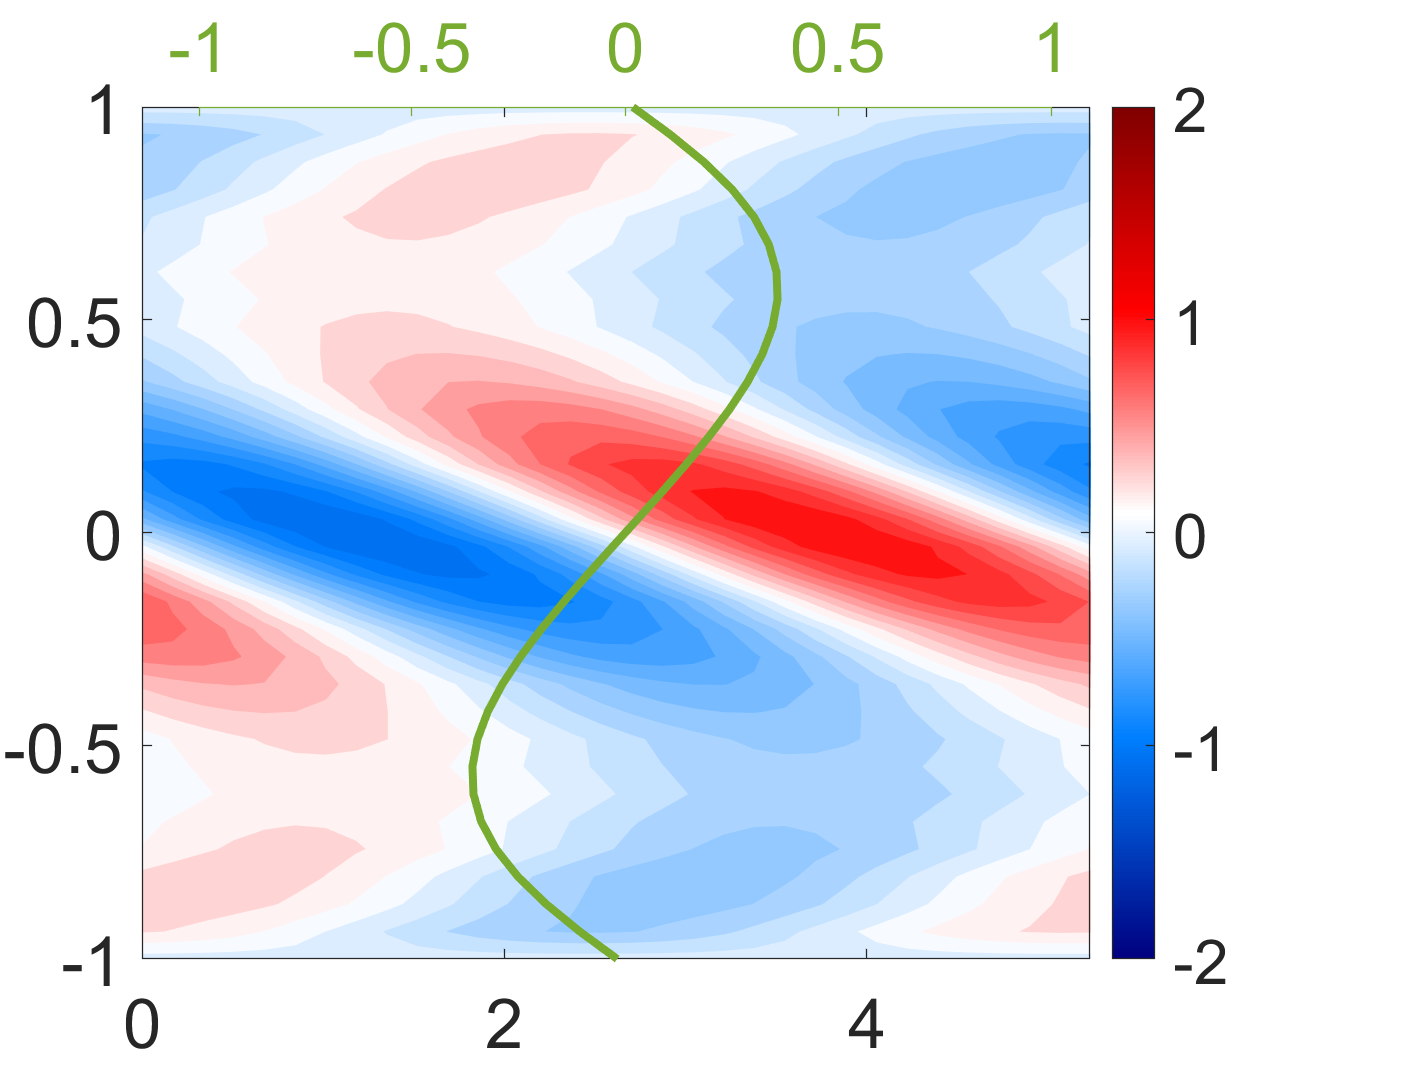

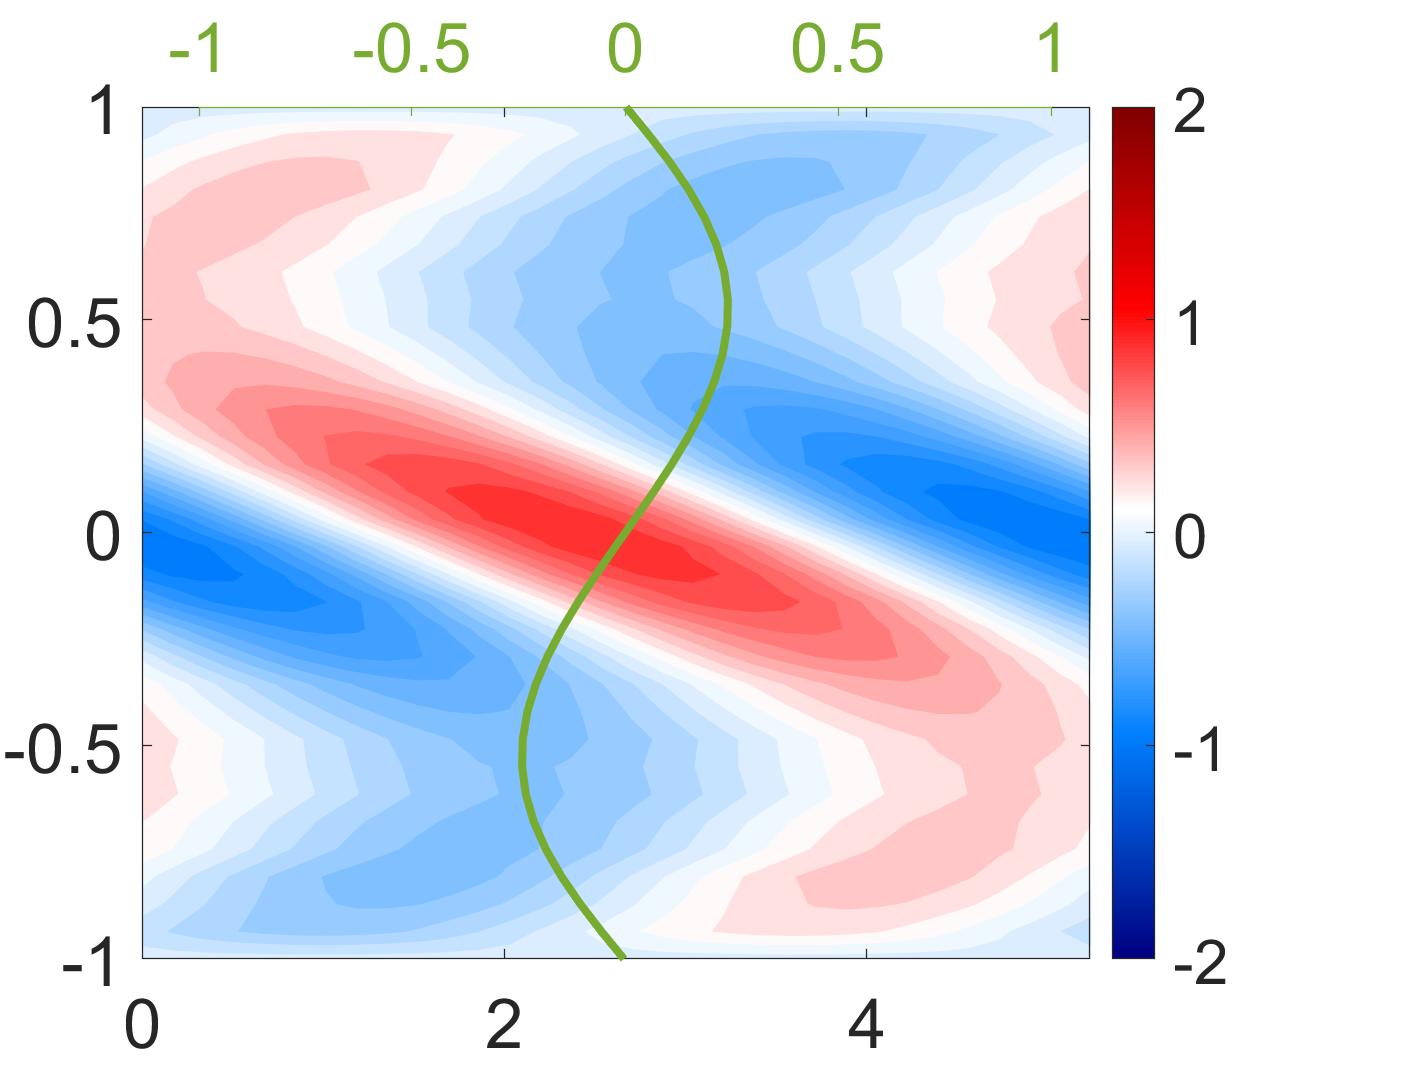

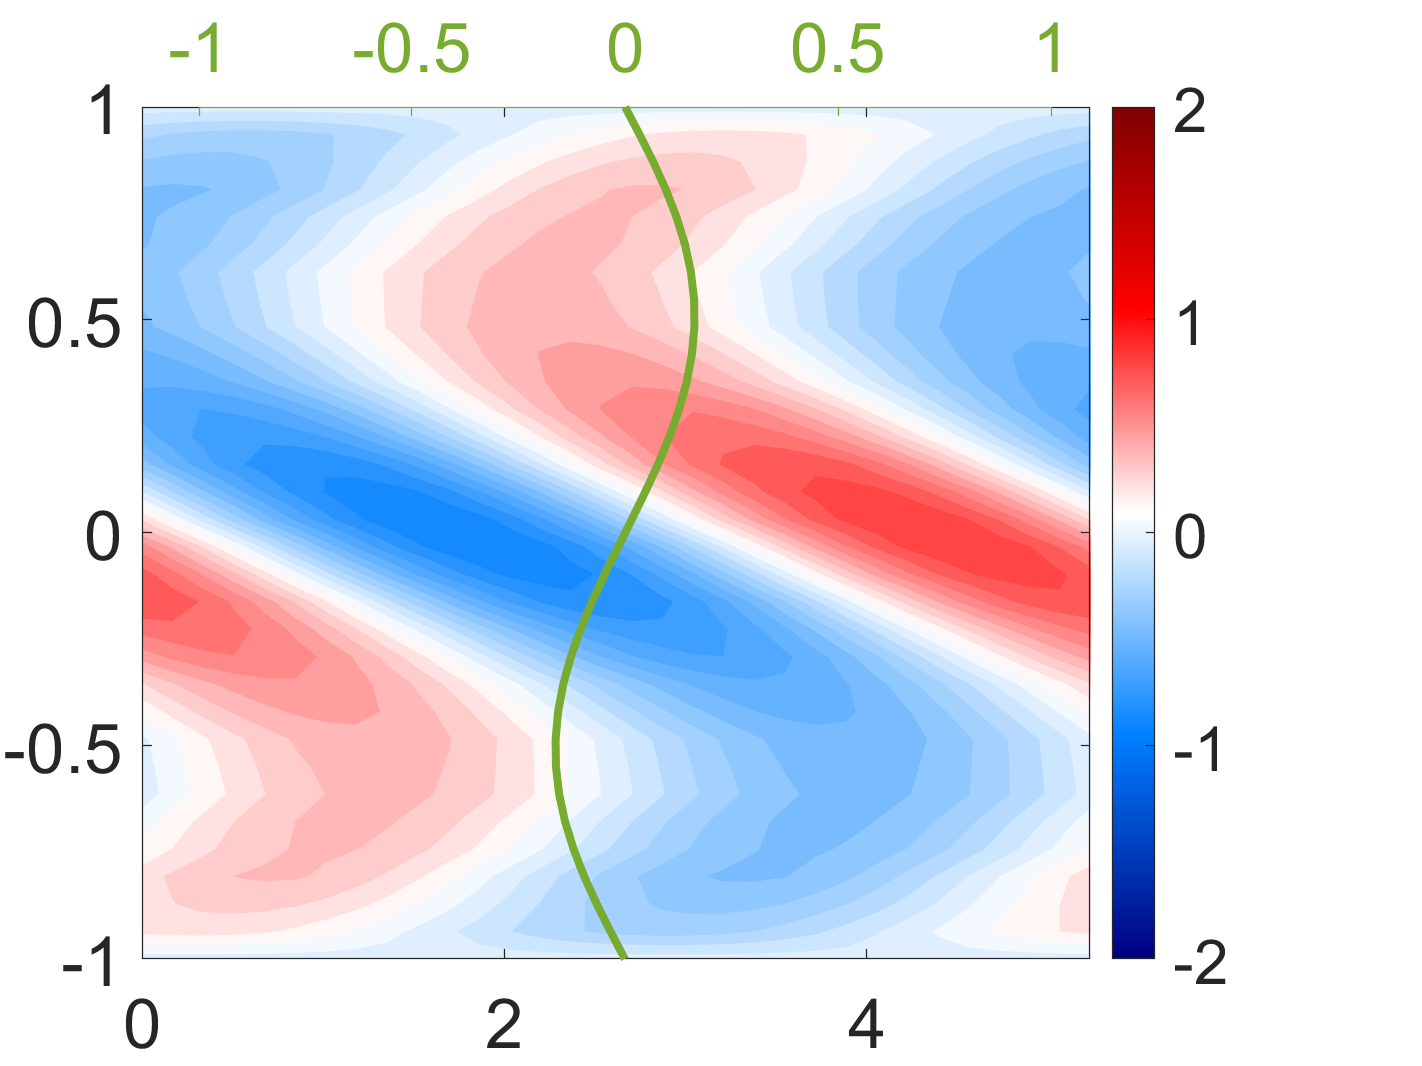

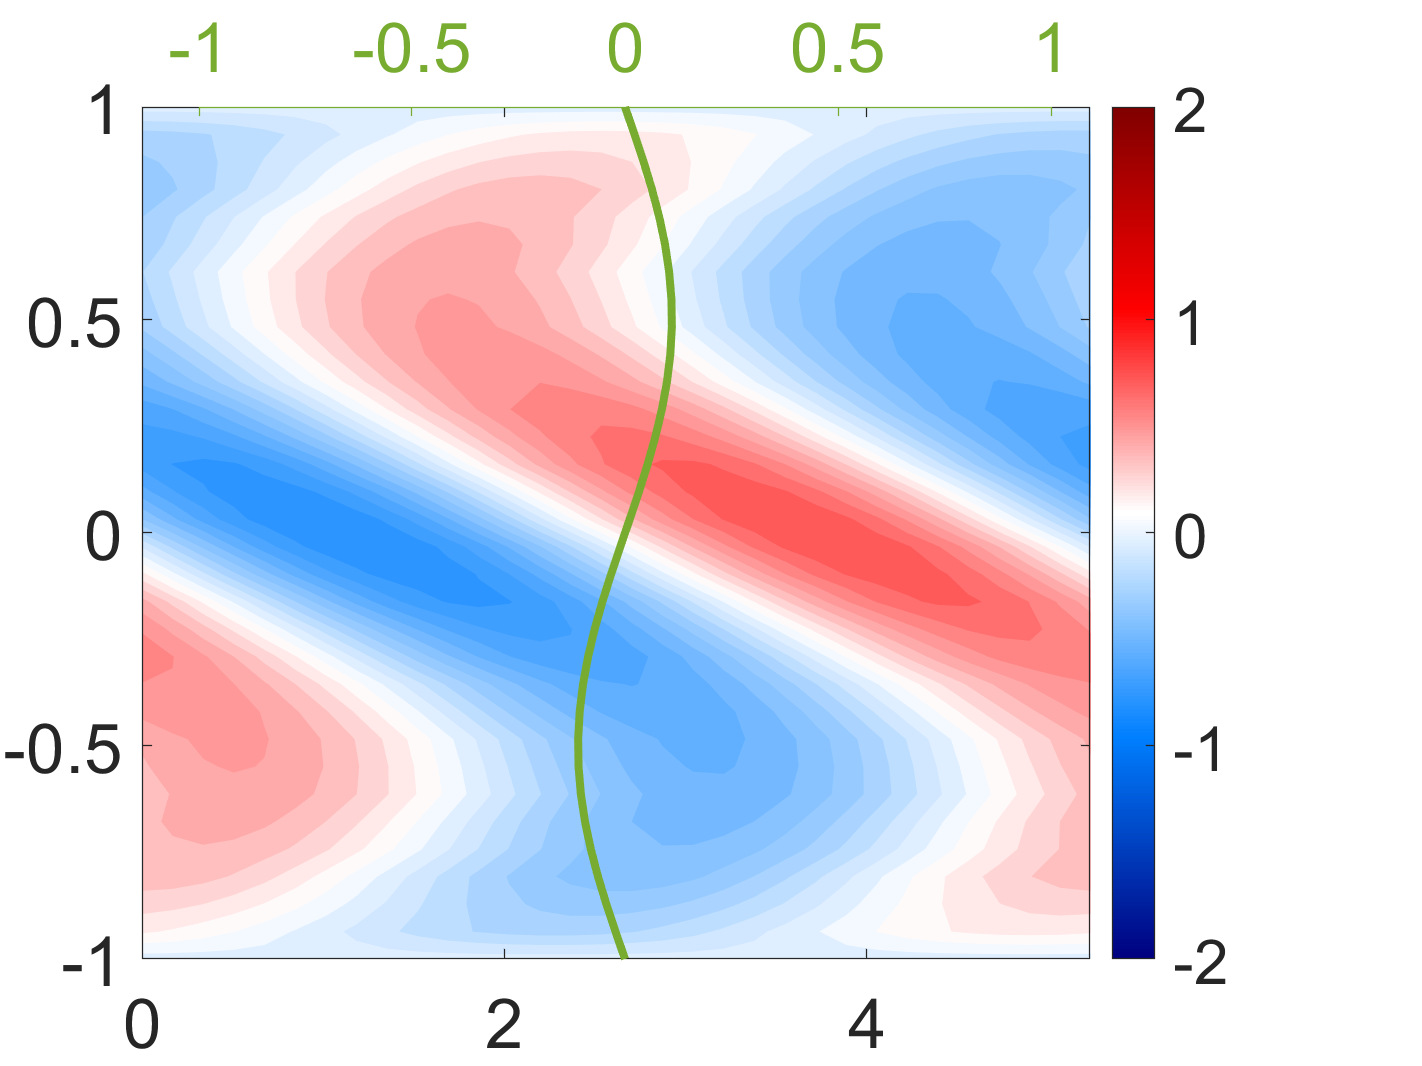

% for j3 = 1:length(t0)
%     if ~isempty(all_eigenvectors{j3})
%         % Full spatial grid (including boundaries)
% %         x_full = [-1,x,1];  % Size N x 1
%         Nx = 32;
% %          x_full = linspace(0,2*pi/a,Nx);
%         kx = a; kz = b;
%         k2 = kx^2 + kz^2;
%         
%         % Choose the first time step for mode visualization
%         j1 = 1;
%         t_current = t0(j3) + j1*dt;
%         
%        % After getting eigenvector q
%         [~, min_idx] = min(all_eigenvalues{j3}{j1});
%         q = all_eigenvectors{j3}{j1}(:, min_idx);
%         
%         % Split state vector
%         v_interior = q(1:(N-2));
%         wy_interior = q((N-2)+1:end);
%         
%         % Pad with boundary zeros (now size N)
%         v_full = [0; v_interior; 0];
%         wy_full = [0; wy_interior; 0];
%         
%         % Compute ∂v/∂y at INTERIOR points
%         Dv_interior = D * v_interior;  % D: (N-2)x(N-2) matrix
%         Dv_full = [0; Dv_interior; 0]; % Pad boundaries
%         
%         % Compute velocity components (now all size N)
% %         kx = a; kz = b;
% %         k2 = kx^2 + kz^2;
%         u_hat = (1/k2) * (1i*kx * Dv_full - 1i*kz * wy_full);
%         v_hat = v_full;
%         w_hat = (1/k2) * (1i*kz * Dv_full + 1i*kx * wy_full);
%         
% %         u = real(u_hat.*exp(1i*kx*x_full));
% 
%         y_grid = linspace(-1, 1, N)';
%         x_grid = linspace(0, 2*pi/a, Nx)';
%         [X, Y] = meshgrid(x_grid, y_grid);
%         
%         % Reconstruct physical space perturbation
%         u_physical = real(u_hat .* exp(1i*a*X));
%         v_physical = real(v_hat .* exp(1i*a*X));
%         w_physical = imag(w_hat .* exp(1i*a*X));
%         max_abs = max(abs(u_physical(:)));
%         c_limits = [-max_abs, max_abs];
%         % Plot
%         U_value = U_yi_function(t_current);  % U_value at y_grid points
% 
%         figure(j3);
%         plot(D, U_value, 'k-', 'LineWidth', 2);
%         contourf(X, Y, u_physical, 20, 'LineColor', 'none');
%         colorbar;
%         colormap(bluewhitered);
%         caxis(c_limits);
%         xlabel('$x$','Interpreter','latex');
%         ylabel('$y$','Interpreter','latex');
%         title(sprintf('Perturbation u at t_0=%.1f (\\alpha=%.2f, \\beta=%.2f)', t0(j3), a, b));
%         set(gca, 'FontSize', 12);
%         
%        
%     end
% end
% 
% 




for j3 = 1:length(t0)
    if ~isempty(all_eigenvectors{j3})
               % Full spatial grid (including boundaries)
%         x_full = [-1,x,1];  % Size N x 1
        Nx = 32;
%          x_full = linspace(0,2*pi/a,Nx);
        kx = a; kz = b;
        k2 = kx^2 + kz^2;
        
        % Choose the first time step for mode visualization
%         j1 = 1;
        
       % After getting eigenvector q
       for j1_ind = 1:length(t0)
        max_eig(j1_ind) = max(all_eigenvalues{j3}{j1_ind});
       end
%         [~,j1_max] = max(max_eig);
        j1_max = 1;
        [~,max_idx] = max(all_eigenvalues{j3}{j1_max});
        t_current = t0(j3) + (j1_max-1)*dt;

        
        
        q = all_eigenvectors{j3}{j1_max}(:, max_idx);
        q = inv(V)*q;
        % Split state vector
        v_interior = q(1:(N-2));
        wy_interior = q((N-2)+1:end);
        
        % Pad with boundary zeros (now size N)
        v_full = [0; v_interior; 0];
        wy_full = [0; wy_interior; 0];
        
        % Compute ∂v/∂y at INTERIOR points
        Dv_interior = D * v_interior;  % D: (N-2)x(N-2) matrix
        Dv_full = [0; Dv_interior; 0]; % Pad boundaries
        
        % Compute velocity components (now all size N)
%         kx = a; kz = b;
%         k2 = kx^2 + kz^2;
        u_hat = (1/k2) * (1i*kx * Dv_full - 1i*kz * wy_full);
        v_hat = v_full;
        w_hat = (1/k2) * (1i*kz * Dv_full + 1i*kx * wy_full);
        
%         u = real(u_hat.*exp(1i*kx*x_full));

        y_grid = linspace(-1, 1, N)';
        x_grid = linspace(0, 2*pi/a, Nx)';
        [X, Y] = meshgrid(x_grid, y_grid);
        
        % Reconstruct physical space perturbation
        u_physical = real(u_hat .* exp(1i*a*X));
        v_physical = real(v_hat .* exp(1i*a*X));
        w_physical = imag(w_hat .* exp(1i*a*X));
        max_abs = max(abs(u_physical(:)));
%         c_limits = [-max_abs, max_abs];
%         c_limits = [-3,3];
        U_interior = U_yi_function(t_current);
        g_current = exp(-k0 * t_current);
        U_full   = [-g_current; U_interior(:); +g_current];  % size N×1
        x_pos    = pi/a;                                    % center in x
        u_shift  = U_full + x_pos;                          % shifted x‐coordinate
        
        figure(j3); clf;
        set(gcf,'Position',[100 100 800 600]);
        % 1) Primary axes for the contour:
        ax1 = axes('Position',[0.10 0.10 0.75 0.8]);
        contourf(ax1, X, Y, u_physical, 20, 'LineColor','none');
        colormap(ax1, bluewhitered);
        colorbar(ax1,'Location','eastoutside');
        caxis(ax1,[-2 2]);
        set(ax1,'FontSize',26,'Box','on');
        
        



        % 2) Overlay a second axes for U(y):
        ax2 = axes('Position',get(ax1,'Position'), ...
                   'XAxisLocation','top', ...
                   'YAxisLocation','right', ...
                   'Color','none', ...
                   'YTick',[], ...      % hide its y‑ticks
                   'Box','off', ...
                   'XColor','#77AC30', ...
                   'FontSize',26);
        set(ax2, 'YColor', 'none');      % <— hide that vertical line

        
        % 3) Link Y‑limits so the laminar curve sits at the correct vertical positions:
        linkprop([ax1 ax2],{'YLim'});
        ylim(ax2, ax1.YLim);
        
        % 4) Give ax2 its own X‑limits = [-1,1] (laminar velocity range):
        xlim(ax2, [-1 1]);
        
        % 5) Force equal data‑unit aspect on ax2:
        %    one “unit” in x (e.g. from -1 to 0) equals one “unit” in y
        daspect(ax2, [1 1 1]);
        
        % 6) Set evenly‑spaced ticks from -1 to +1:
        lam_ticks = linspace(-1,1,5);
        set(ax2, 'XTick', lam_ticks, 'XTickLabel', arrayfun(@num2str, lam_ticks,'Uni',0));
        % after creating ax2 …
        set(ax2, 'Units', 'centimeters');          % work in cm
        pos = get(ax2, 'Position');                % [left bottom width height]
        pos(1) = pos(1) - 0.75;                       % move left by 1 cm
        set(ax2, 'Position', pos, 'Units', 'normalized');  % apply and switch back
%         axis(ax2,'equal');            

        
        
        % 7) Plot the laminar profile on ax2:
        hold(ax2,'on');
        plot(ax2, U_full, y_grid, 'LineWidth',3, 'Color','#77AC30');
        hold(ax2,'off');

% % 
% %         figure(j3);
% %         set(gcf, 'Position', [100, 100, 800, 600]);
% %         ax1 = axes;
% %         
% %         % Plot contour of u
% %         contourf(X, Y, u_physical, 20, 'LineColor', 'none');
% %         colormap(bluewhitered);
% %         cbh = colorbar('Location', 'eastoutside');
% %         caxis(c_limits);
% %         set(ax1, 'FontSize', 26, 'Box', 'on');
% %         hold on;
% %         
% %         % Plot base flow at x = pi/a
% %         U_interior = U_yi_function(t_current);
% %         g_current = exp(-k0 * t_current);
% %         U_full = [-g_current; U_interior(:); g_current];
% %         x_pos = pi/a;
% %         h_base = plot(U_full + x_pos, y_grid, 'LineStyle','-', 'Color','#77AC30', 'LineWidth', 3);
% %         hold off;
% %         
% %         % --- Create second top axis (ax2) ---
% %         ax2 = axes('Position', get(ax1, 'Position')); % Same position as ax1
% %         set(ax2, 'XAxisLocation', 'top', 'Color', 'none', 'YColor', 'none');
% %         linkaxes([ax1, ax2], 'x'); % Link x-axes
% %         
% %         % Find x limits
% %         current_x_min = ax1.XLim(1);
% %         current_x_max = ax1.XLim(2);
% %         
% %         % Adjust top axis tick labels to map x_pos → 0 in [-1, 1] frame
% %         scale_factor = max(abs([current_x_max - x_pos, x_pos - current_x_min]));
% %         xticks_top = linspace(x_pos - scale_factor, x_pos + scale_factor, 5);
% %         xtick_labels_top = linspace(-1, 1, 5);
% %         
% %         set(ax2, 'XTick', xticks_top);
% %         set(ax2, 'XTickLabel', num2cell(xtick_labels_top));
% %         set(ax2, 'FontSize', 26, 'XColor', '#77AC30');

% 
%       % Create figure with single axis
%         figure(j3);
%         set(gcf, 'Position', [100, 100, 800, 600]);
%         ax1 = axes;
%         
%         % Plot contour
%         contourf(X, Y, u_physical, 20, 'LineColor', 'none');
%         colormap(bluewhitered);
%         cbh = colorbar('Location', 'eastoutside');
%         caxis(c_limits);
% %         xlabel('x');
% %         ylabel('y');
% %         title(sprintf('$t_0 =%.0f$', t0(j3)));
%         set(ax1, 'FontSize', 26, 'Box', 'on');
%         hold on;
%         
%         % Get and plot base flow
%         U_interior = U_yi_function(t_current);
%         g_current = exp(-k0 * t_current);
%         U_full = [-g_current; U_interior(:); g_current];
%         x_pos = pi/a;  % Center of x-domain
%         h_base = plot(U_full + x_pos, y_grid, 'LineStyle','-', 'Color','#77AC30','LineWidth', 3);
%         h_base = plot(U_full, y_grid, 'LineStyle','-', 'Color','#77AC30','LineWidth', 3);
% 
%         hold off;
% 
%          % Create a second axis on top of ax1
%         ax2 = axes('Position', get(ax1, 'Position')); % Same position as ax1
%         set(ax2, 'XAxisLocation', 'top', 'Color', 'none', 'YColor', 'none');
%         linkaxes([ax1, ax2], 'x'); % Link the x-axes of ax1 and ax2
% 
%         % Plot the same data (h_base) on the new axis (ax2)
%         set(h_base, 'Parent', ax2);  % Move h_base to the second axis (ax2)
% 
%         % Find the current x-range (min and max) of ax1
%         current_x_min = ax1.XLim(1);  % Get the x-min from ax1
%         current_x_max = ax1.XLim(2);  % Get the x-max from ax1
% %         current_x_min = -1;  % Get the x-min from ax1
% %         current_x_max = 1;  % Get the x-max from ax1
%         current_x_center = (current_x_min + current_x_max) / 2;  % Calculate the center
% 
%         % Set the x-limits for ax2 to match ax1's limits (same range as ax1)
%         xlim(ax2, [current_x_min, current_x_max]);
% 
%         % Map the x-range to [-1, 1] for the top axis (ax2)
%         scale_factor = (current_x_max - current_x_min) / 2;  % Scale factor to map to [-1, 1]
%         set(ax2, 'XTick', linspace(current_x_min, current_x_max, 5));  % Set the x-ticks for ax2
% 
%         % Adjust tick labels to reflect the [-1, 1] range
%         ax2.XTickLabel = num2cell(linspace(-1, 1, 5));  % Map tick labels from -1 to 1
%         set(ax2, 'FontSize', 26, 'XColor', '#77AC30');
%   
    end
end